# **CAN - Counter and CRC Message Protection**

This example shows how to add counter and CRC message protection for CAN and CAN FD messages to be used with a Speedgoat CAN I/O module. The Simulink® model implements a loopback by sending CAN FD messages from channel 1 to channel 2.

In the Simulink model, the following concepts are featured:

- CAN FD bus data types

- Packing and unpacking a CAN FD message based on a database file

- Insertion and validation of a counter value for CAN message protection

- Insertion and validation of a CRC value for CAN message protection

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with an IO602, IO603, or an IO691 CAN I/O module installed

- 1x CAN Loopback Test Cable with terminator resistor (120 Ω)

### Connection Diagram

To run this example, CAN channel 1 and CAN channel 2 must be connected with a terminated CAN cable. As this example can be executed with an IO602, IO603, or an IO691, refer to the pin mapping for your CAN I/O module to connect channel 1 and channel 2:

[IO602 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_pin_mapping) / [IO603 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io603_pin_mapping) / [IO691 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io691_pin_mapping)

## Open and Configure the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_CAN_CounterAndCRC';
open_system(modelName);

### Select CAN I/O Module

First, the specific CAN I/O module that you are using must be selected in the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block. In every [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block, a unique **Module ID** is set to link the [CAN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_read) and [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) blocks in the rest of the model to this setup block. If there is only one IO602, IO603, or IO691 in the target, the **Module ID** can remain set to 1.

 
% open the CAN setup block to select your CAN I/O module
speedgoat.model.highlight([modelName '/CAN and LIN Setup '],'Parameter','moduleType');

### Select CAN Protocol Mode

After selecting the correct CAN I/O module, channel 1 and channel 2 are configured for protocol mode "CAN FD". You can do this using the drop-down in the mask or with the following code section. Unused CAN channels can be disabled.

 
% configure CAN channel 1 and 2 to CAN FD
set_param([modelName '/CAN and LIN Setup '],'canChn1','CAN-FD');
set_param([modelName '/CAN and LIN Setup '],'canChn2','CAN-FD');

When a channel is enabled, the baud rate can be configured in the tab shown for each channel. For CAN FD, two baud rates must be set in the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block, as the data part of the CAN FD frame can be transmitted at a different–usually faster–rate.

The protocol mode "CAN FD" must also be configured in all [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert), [CRC Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_validation), [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert), and [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) blocks. You can do this using the drop-down in the mask or with the following code section.

% configure CRC and Counter Insert and Validation blocks to CAN FD
set_param([modelName '/Counter Insert '],'parProtocol','CAN-FD');
set_param([modelName '/CRC Insert '],'parProtocol','CAN-FD');
set_param([modelName '/Counter Validation '],'parProtocol','CAN-FD');
set_param([modelName '/CRC Validation '],'parProtocol','CAN-FD');

set_param([modelName '/Counter Insert 1'],'parProtocol','CAN-FD');
set_param([modelName '/CRC Insert 1'],'parProtocol','CAN-FD');
set_param([modelName '/Counter Validation 1'],'parProtocol','CAN-FD');
set_param([modelName '/CRC Validation 1'],'parProtocol','CAN-FD');

set_param([modelName '/Counter Insert 2'],'parProtocol','CAN-FD');
set_param([modelName '/CRC Insert 2'],'parProtocol','CAN-FD');
set_param([modelName '/Counter Validation 2'],'parProtocol','CAN-FD');
set_param([modelName '/CRC Validation 2'],'parProtocol','CAN-FD');

set_param([modelName '/Counter Insert 3'],'parProtocol','CAN-FD');
set_param([modelName '/Counter Validation 3'],'parProtocol','CAN-FD');

## Model Description

The model is split into four main loopback paths, where CAN FD messages are sent from channel 1 to channel 2. The transmitted CAN messages are prepared by inserting a counter value that increments per message into the payload, along with a CRC value computed over the entire payload. Consequently, the counter and CRC values in the received CAN messages are extracted and validated to confirm data integrity and completeness.

You have already used the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to configure the CAN I/O module and its channels; the remaining blocks to configure are the [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert), [CRC Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_validation), [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert), and [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) blocks, which insert and validate message protection information for the CAN message payload.

### Basics of CAN Counter and CRC Message Protection Blocks

By default, the [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) and [Counter Insert ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert)blocks process CAN_MESSAGE_BUS or CAN_FD_MESSAGE_BUS data type signals. This means the Insert blocks must be placed between the CAN FD Pack block and the [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block. The CRC value is always calculated over the entire payload, excluding the bits reserved for the CRC value itself; therefore, the CRC Insert block must be placed directly before the CAN Write block. The Counter Insert block controls the counter value according to the configured parameters and inserts it into the payload at the specified location. Because the counter insertion does not depend on the payload content, its placement can be chosen independently.

% highlight CRC Insert and Counter Insert blocks
speedgoat.model.highlight([modelName '/CRC Insert ']);
speedgoat.model.highlight([modelName '/Counter Insert ']);

By default, the [CRC Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_validation) and [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) blocks receive CAN_MESSAGE_BUS or CAN_FD_MESSAGE_BUS data type signals. This means the CAN or CAN FD message input of the validation blocks must be connected directly to a [CAN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_read) block CAN Message or CAN FD Message output port.

% highlight CRC Validation and Counter Validation blocks
speedgoat.model.highlight([modelName '/CRC Validation ']);
speedgoat.model.highlight([modelName '/Counter Validation ']);

As an alternative to CAN_MESSAGE_BUS or CAN_FD_MESSAGE_BUS data types, the CAN Counter and CRC Insert and Validation blocks also support uint8 byte array data type signals. This option can be used when applying message protection before packing or when manually packing the CAN or CAN FD message. An example using a uint8 byte array data type is not covered in this document.

### Individual Counter or CRC Insert and Validation

 
% highlight area Individual Counter or CRC Insert
speedgoat.model.highlight([modelName '/Individual Counter or CRC Insert']);

The CAN Counter and CRC Message Protection blocks can be used on each packed CAN or CAN FD message in their simplest configuration. This example focuses on two CAN FD messages defined in a .dbc file, which is already loaded in the [CAN FD Pack](https://mathworks.com/help/vnt/ug/canfdpack.html) block.

The CAN FD message with ID100 has a signal defined for counter value insertion. The "Message_Protection_Counter_8bit" signal starts at bit 128 in the CAN FD message and is 8 bits long. These values are also configured in the [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) block using the parameters **Counter Location (Bits)** and **Counter Length (Bits)**. The **Internal Counter** parameters can be configured as required; for this example, use the values already configured (**Counter Start Value** = 1, **Counter Stop Value** = 15, ***Counter Step Value*** = 1). The generated and inserted counter value can be monitored on the optional output port, enabled using the **Counter port **parameter.

% highlight counter settings in Counter Insert block
speedgoat.model.highlight([modelName '/Counter Insert '], 'Open', true);

The CAN FD message with ID200 has a signal defined for CRC value insertion. The "Message_Protection_CRC8_0x2F" signal starts at bit 64 in the CAN FD message and is 8 bits long. The signal start bit is configured in the [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) block using the **Bit** **Location **parameter. The signal bit length is implicitly configured in the [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) block using the **CRC Type **parameter. The calculated and inserted CRC value can be monitored on the optional output port, enabled using the **CRC port **parameter.

% highlight CRC settings in CRC Insert block
speedgoat.model.highlight([modelName '/CRC Insert '], 'Open', true);

 
% highlight area Counter or CRC Validation
speedgoat.model.highlight([modelName '/Individual Counter or CRC Validation']);

The [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) block validating the counter value for the CAN FD message with ID100 must use the same configuration as the corresponding [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) block. Similarly, the [CRC Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_validation) block validating the CRC value for the CAN FD message with ID200 must use the same configuration as the corresponding [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) block.

### Sequential Counter or CRC Insert and Validation

% highlight area Sequential Counter and CRC Insert
speedgoat.model.highlight([modelName '/Sequential Counter and CRC Insert']);

The [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) and [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) blocks can be used in sequence to apply both message protection modes to a single CAN or CAN FD message. As in the above example, the CRC Insert block must be the last block directly before the [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block. Additionally, the specified counter and CRC bit locations and lengths within the payload for message ID300 must be applied consistently when configuring the blocks.

In this example, counter and CRC values of different bit widths are used to highlight the versatility of these blocks. The example also illustrates the insertion behavior for counter and CRC values, which are always inserted using little-endian byte order and least-significant-bit-first (LSB-first) bit order. Accordingly, the **Counter Location (Bits)** parameter of the [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) block specifies the bit position of the counter’s least significant bit. The counter value is then inserted bit-by-bit into successive bit positions with increasing bit indices. The same behavior applies to the **Bit Location** parameter of the [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) block.

To validate a received message containing both a counter value and a CRC value, the [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) and [CRC Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_validation) blocks are used individually as in the above example. Validation is performed independently by each block, and the received CAN message bus object remains unchanged and can be unpacked as usual. The validation blocks must therefore be configured consistently with their corresponding insert blocks.

### External Counter and Custom CRC

 
% highlight area External Counter and Custom CRC Insert
speedgoat.model.highlight([modelName '/External Counter and Custom CRC Insert']);

The insertion of counter and CRC values into the payload can be customized, allowing externally provided values or user-defined algorithms to control how these fields are generated and placed. As in the above example, the CRC Insert block must be the last block immediately before the [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block. Additionally, the specified counter and CRC bit locations and lengths within the payload for message ID400 must be applied consistently when configuring the blocks.

Additional customization is available through the **Counter from Input port** parameter in the [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) block. Enabling this option adds an Input port to which an externally provided counter value of type uint8, uint16, or uint32 can be applied. This value is inserted into the payload in place of an internally managed counter value.

CRC insertion can be customized by using a custom CRC algorithm. To do so, the **CRC Type **option must be set to *Custom *in the [CRC Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_insert) block. In addition, a C or C++ file defining the CRC algorithm, along with the corresponding function name, must be specified. Further details–including a template implementation–are provided in the [Custom CRC Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_custom_crc_usage_notes). In this example, the template is used to insert a 12-bit CRC value.

Validation follows the same principles as in the above examples. The [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) and [CRC Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_crc_validation) blocks must be configured consistently with their corresponding insert blocks. When the counter value is provided via the Input port, the Counter Validation block must be configured to expect the same counter sequence, including the configured start value, step, and stop behavior.

### Counter Insert Control

% highlight area Counter Insert Control
speedgoat.model.highlight([modelName '/Counter Insert Control']);

This example demonstrates the counter control functionality, enabled using the **Counter Control Port** parameter of the [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) block. A repeating sequence of [1 0 5 0xFFFF] uint32 values is applied to the Counter Control Input port, with values changing every second. The counter value managed and inserted into the message payload, in accordance with the block parameters, is controlled by this input sequence.

The [Counter Insert](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_insert) block reacts to the input as follows:

- 0 – Reset the counter to the value specified by the **Counter Start Value** parameter

- 1 – Increment the counter at every sample step

- d > 1 – Increment the counter at every d-th sample step (e.g., d = 5 increments every 5th step)

- 0xFFFF – Hold the current counter value

The [Counter Validation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_counter_validation) block verifies the received counter values against the expected sequence derived from the configured parameters. Any mismatch between the inserted counter value and the expected sequence triggers a validation flag. Because the Counter Control input for the insert block can alter the counter sequence, the validation block flags any holds, resets, or increment decimations as *invalid*. Specifically, the Alive Counter check fails on a counter hold, and the Sequence Counter check is invalid for resets or increment decimations.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

  
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download the real-time application to the target machine and set stop time
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
% This will allow to use the Simulink scopes in the model for visualization
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode
set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Wait until the real-time application reaches the stop time of 10 seconds

### Results

To verify that the loopback is working successfully, inspect the scopes connected to the received CAN FD messages. Below are screenshots of the expected results.

It is possible to change parameters of the source signal blocks–the changes must be visible on the receiving end immediately.

**CAN FD Read Ch2 - Message A ID100 - Counter 8-Bit**

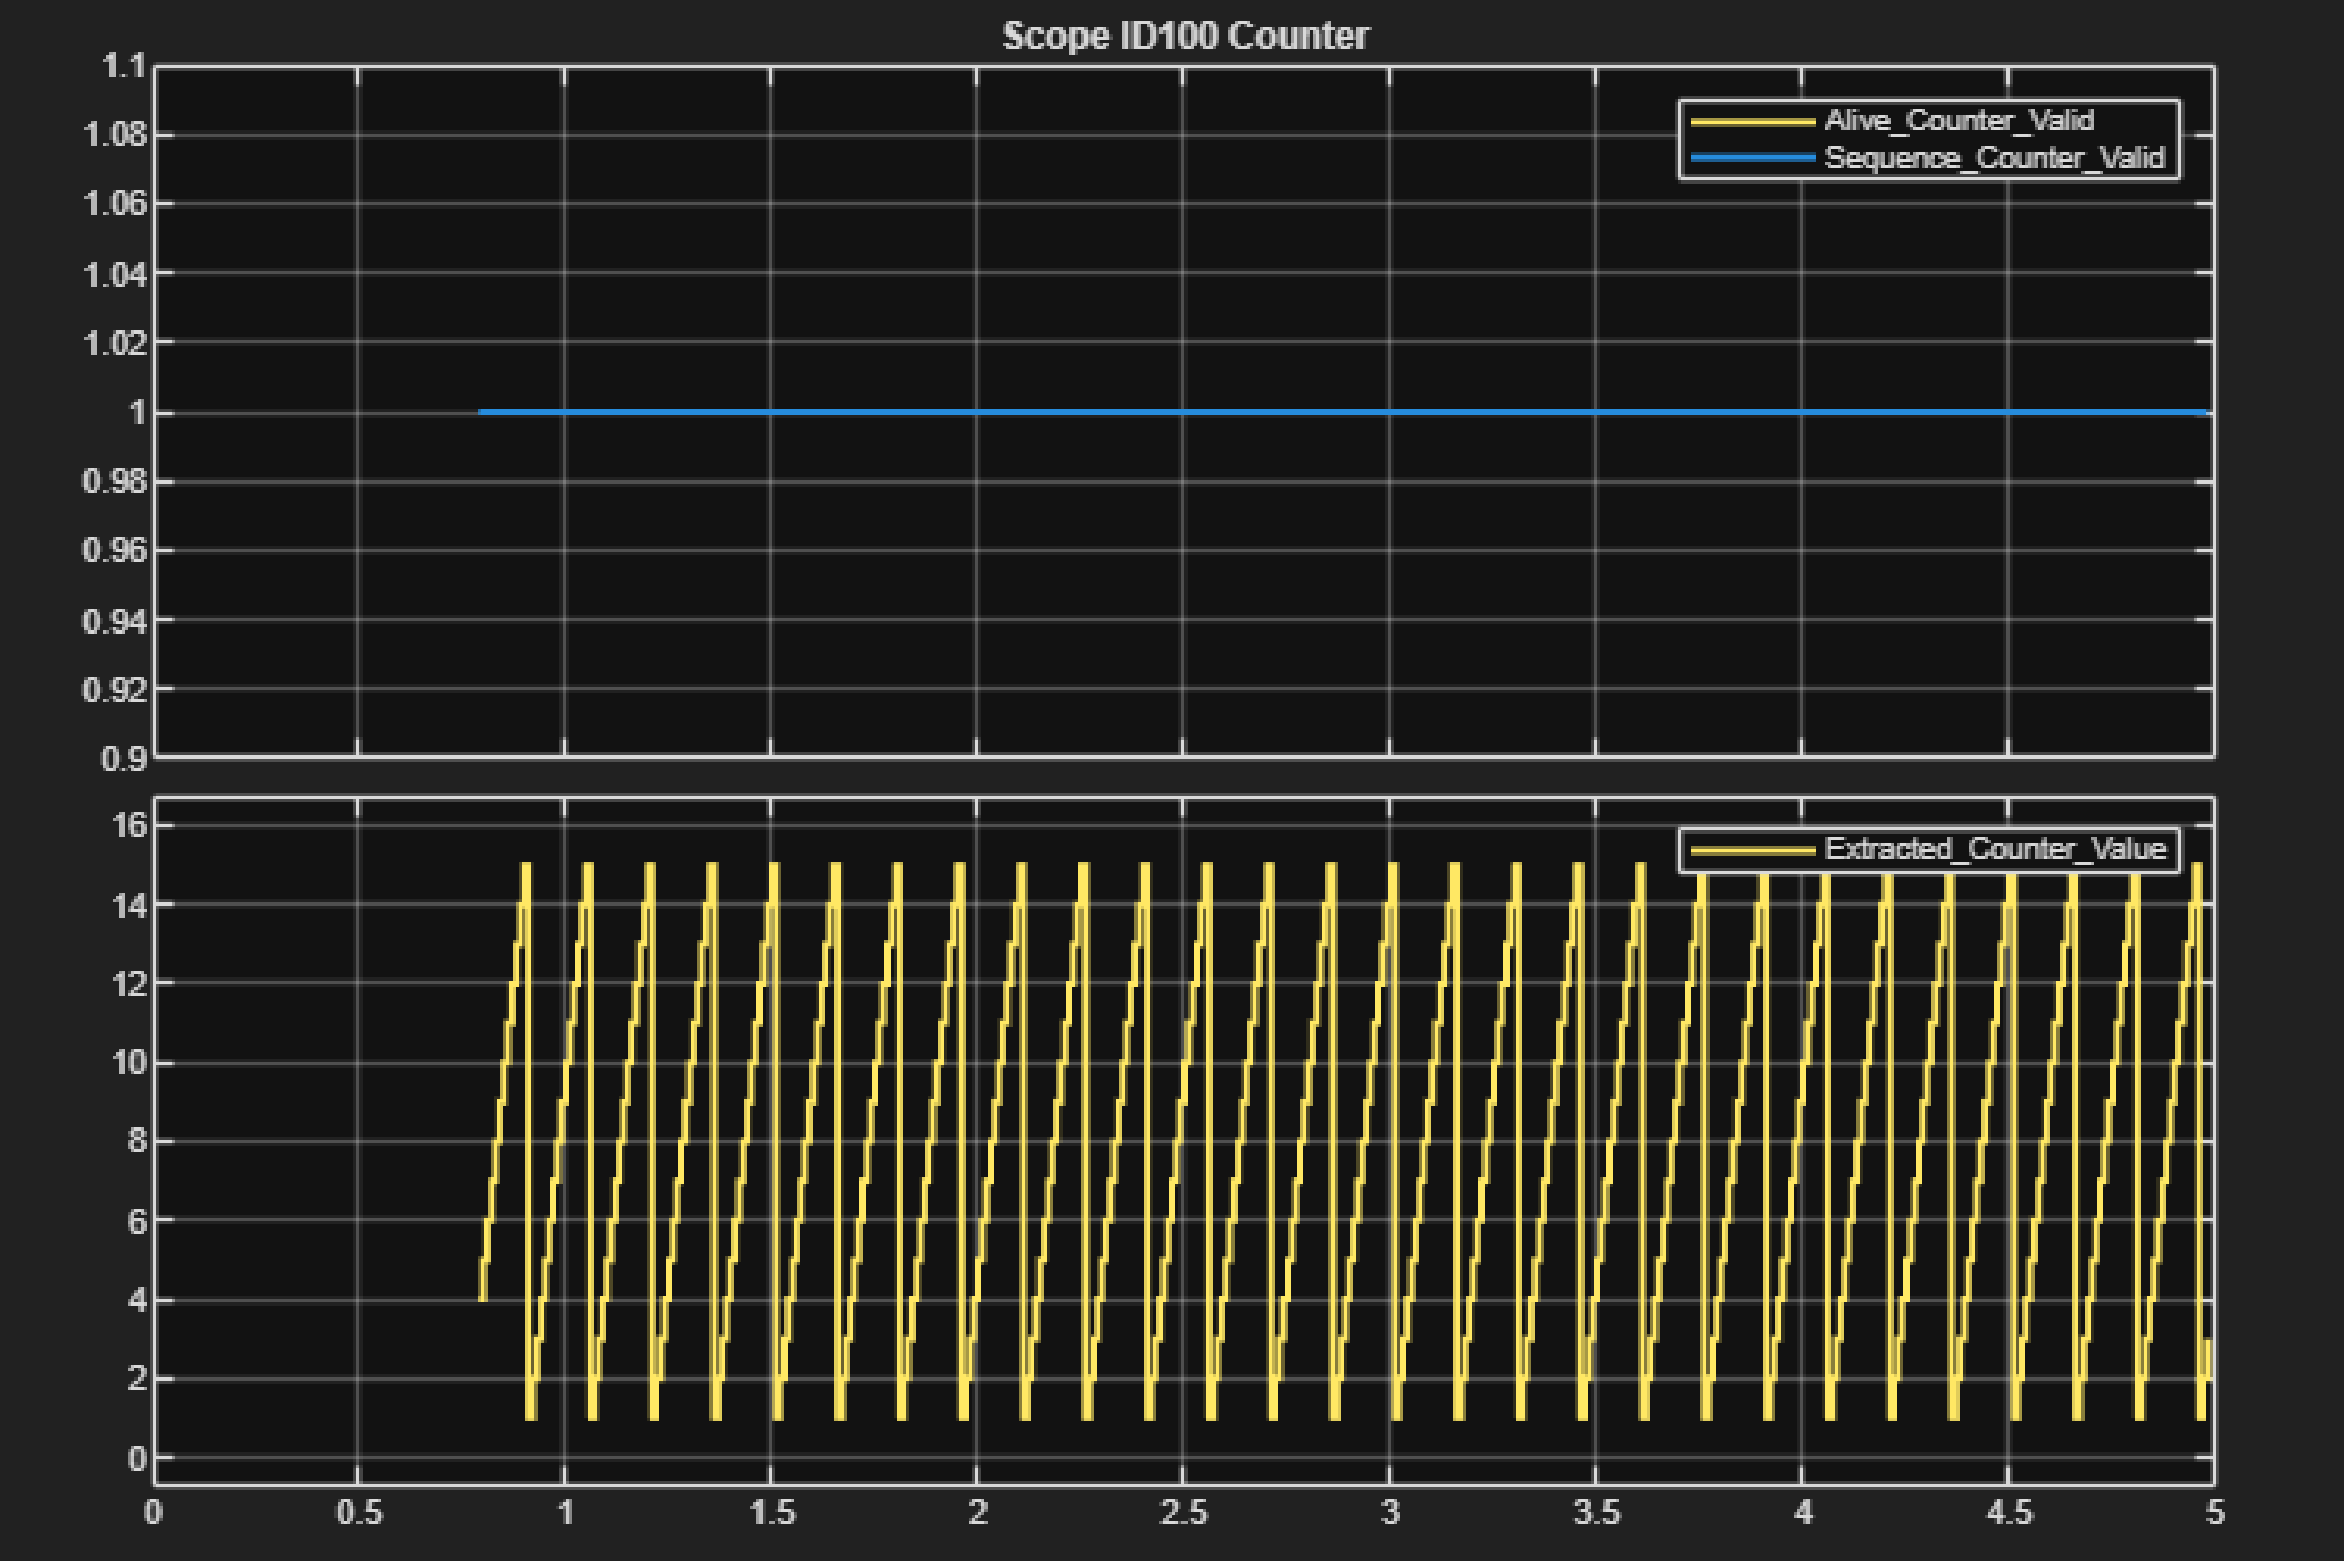

**CAN FD Read Ch2 - Message B ID200 - CRC8 - 0x2F**

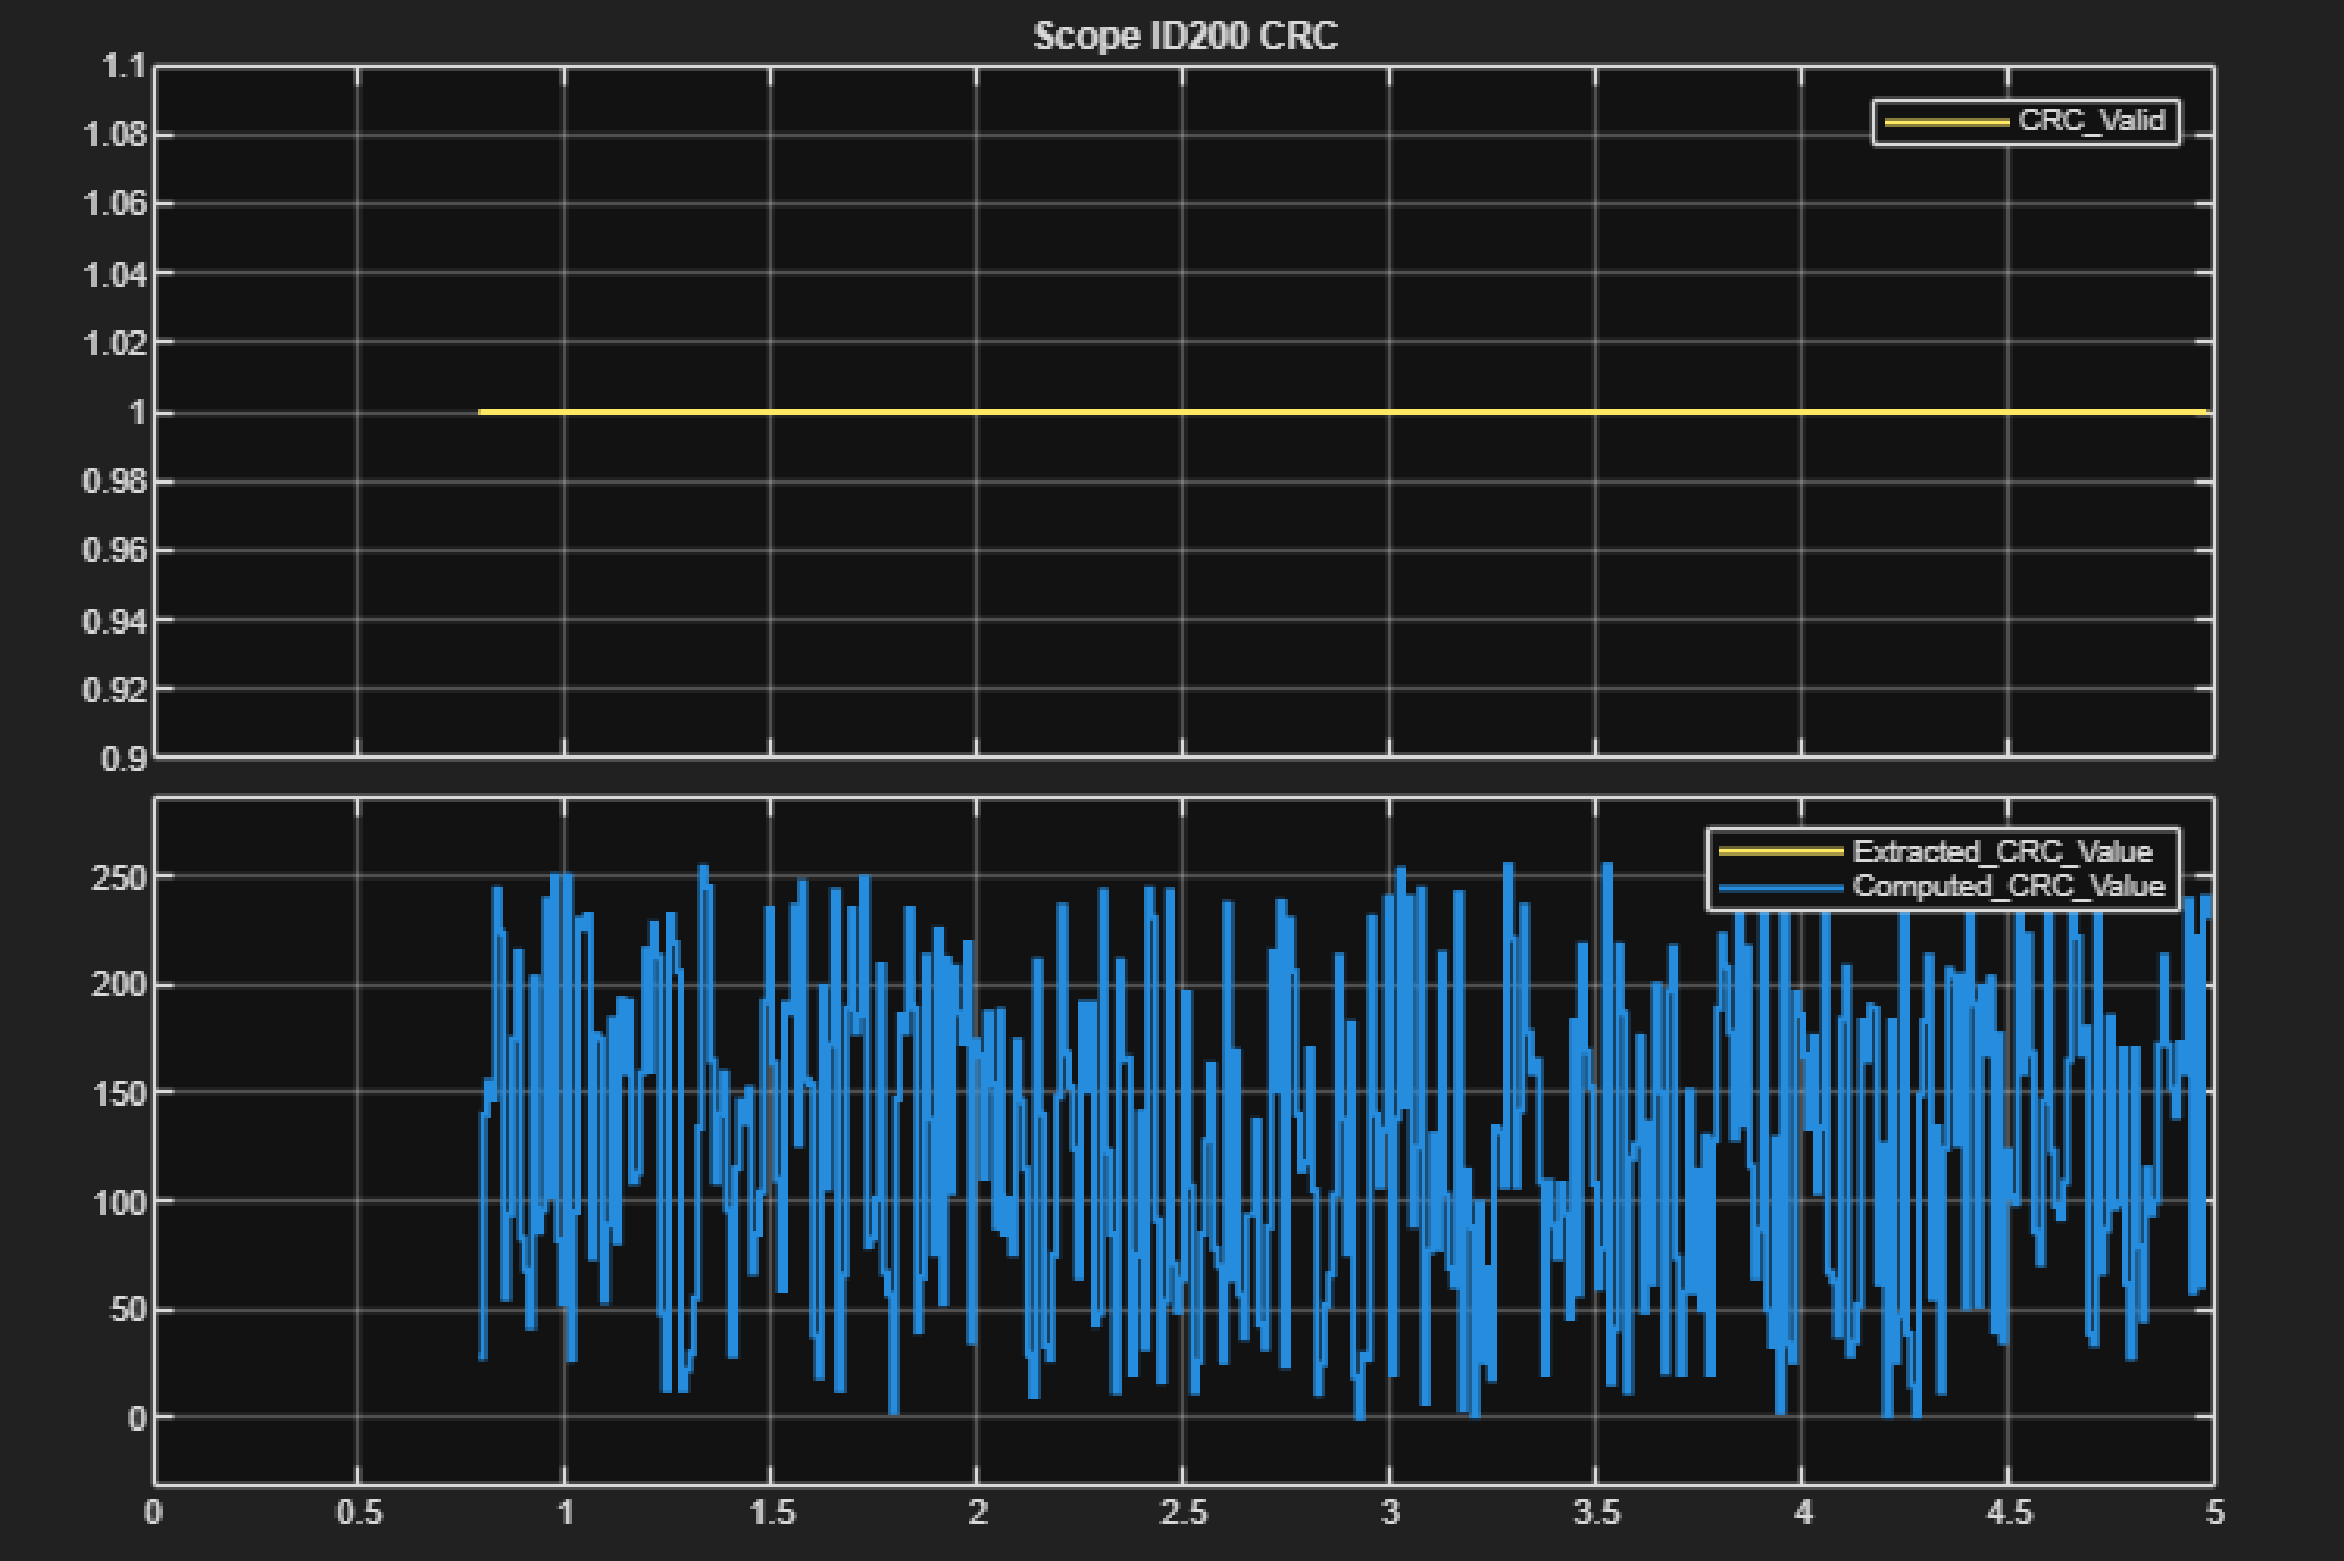

**CAN FD Read Ch2 - Message C ID300 - Counter 12-Bit and CRC16 ARC**

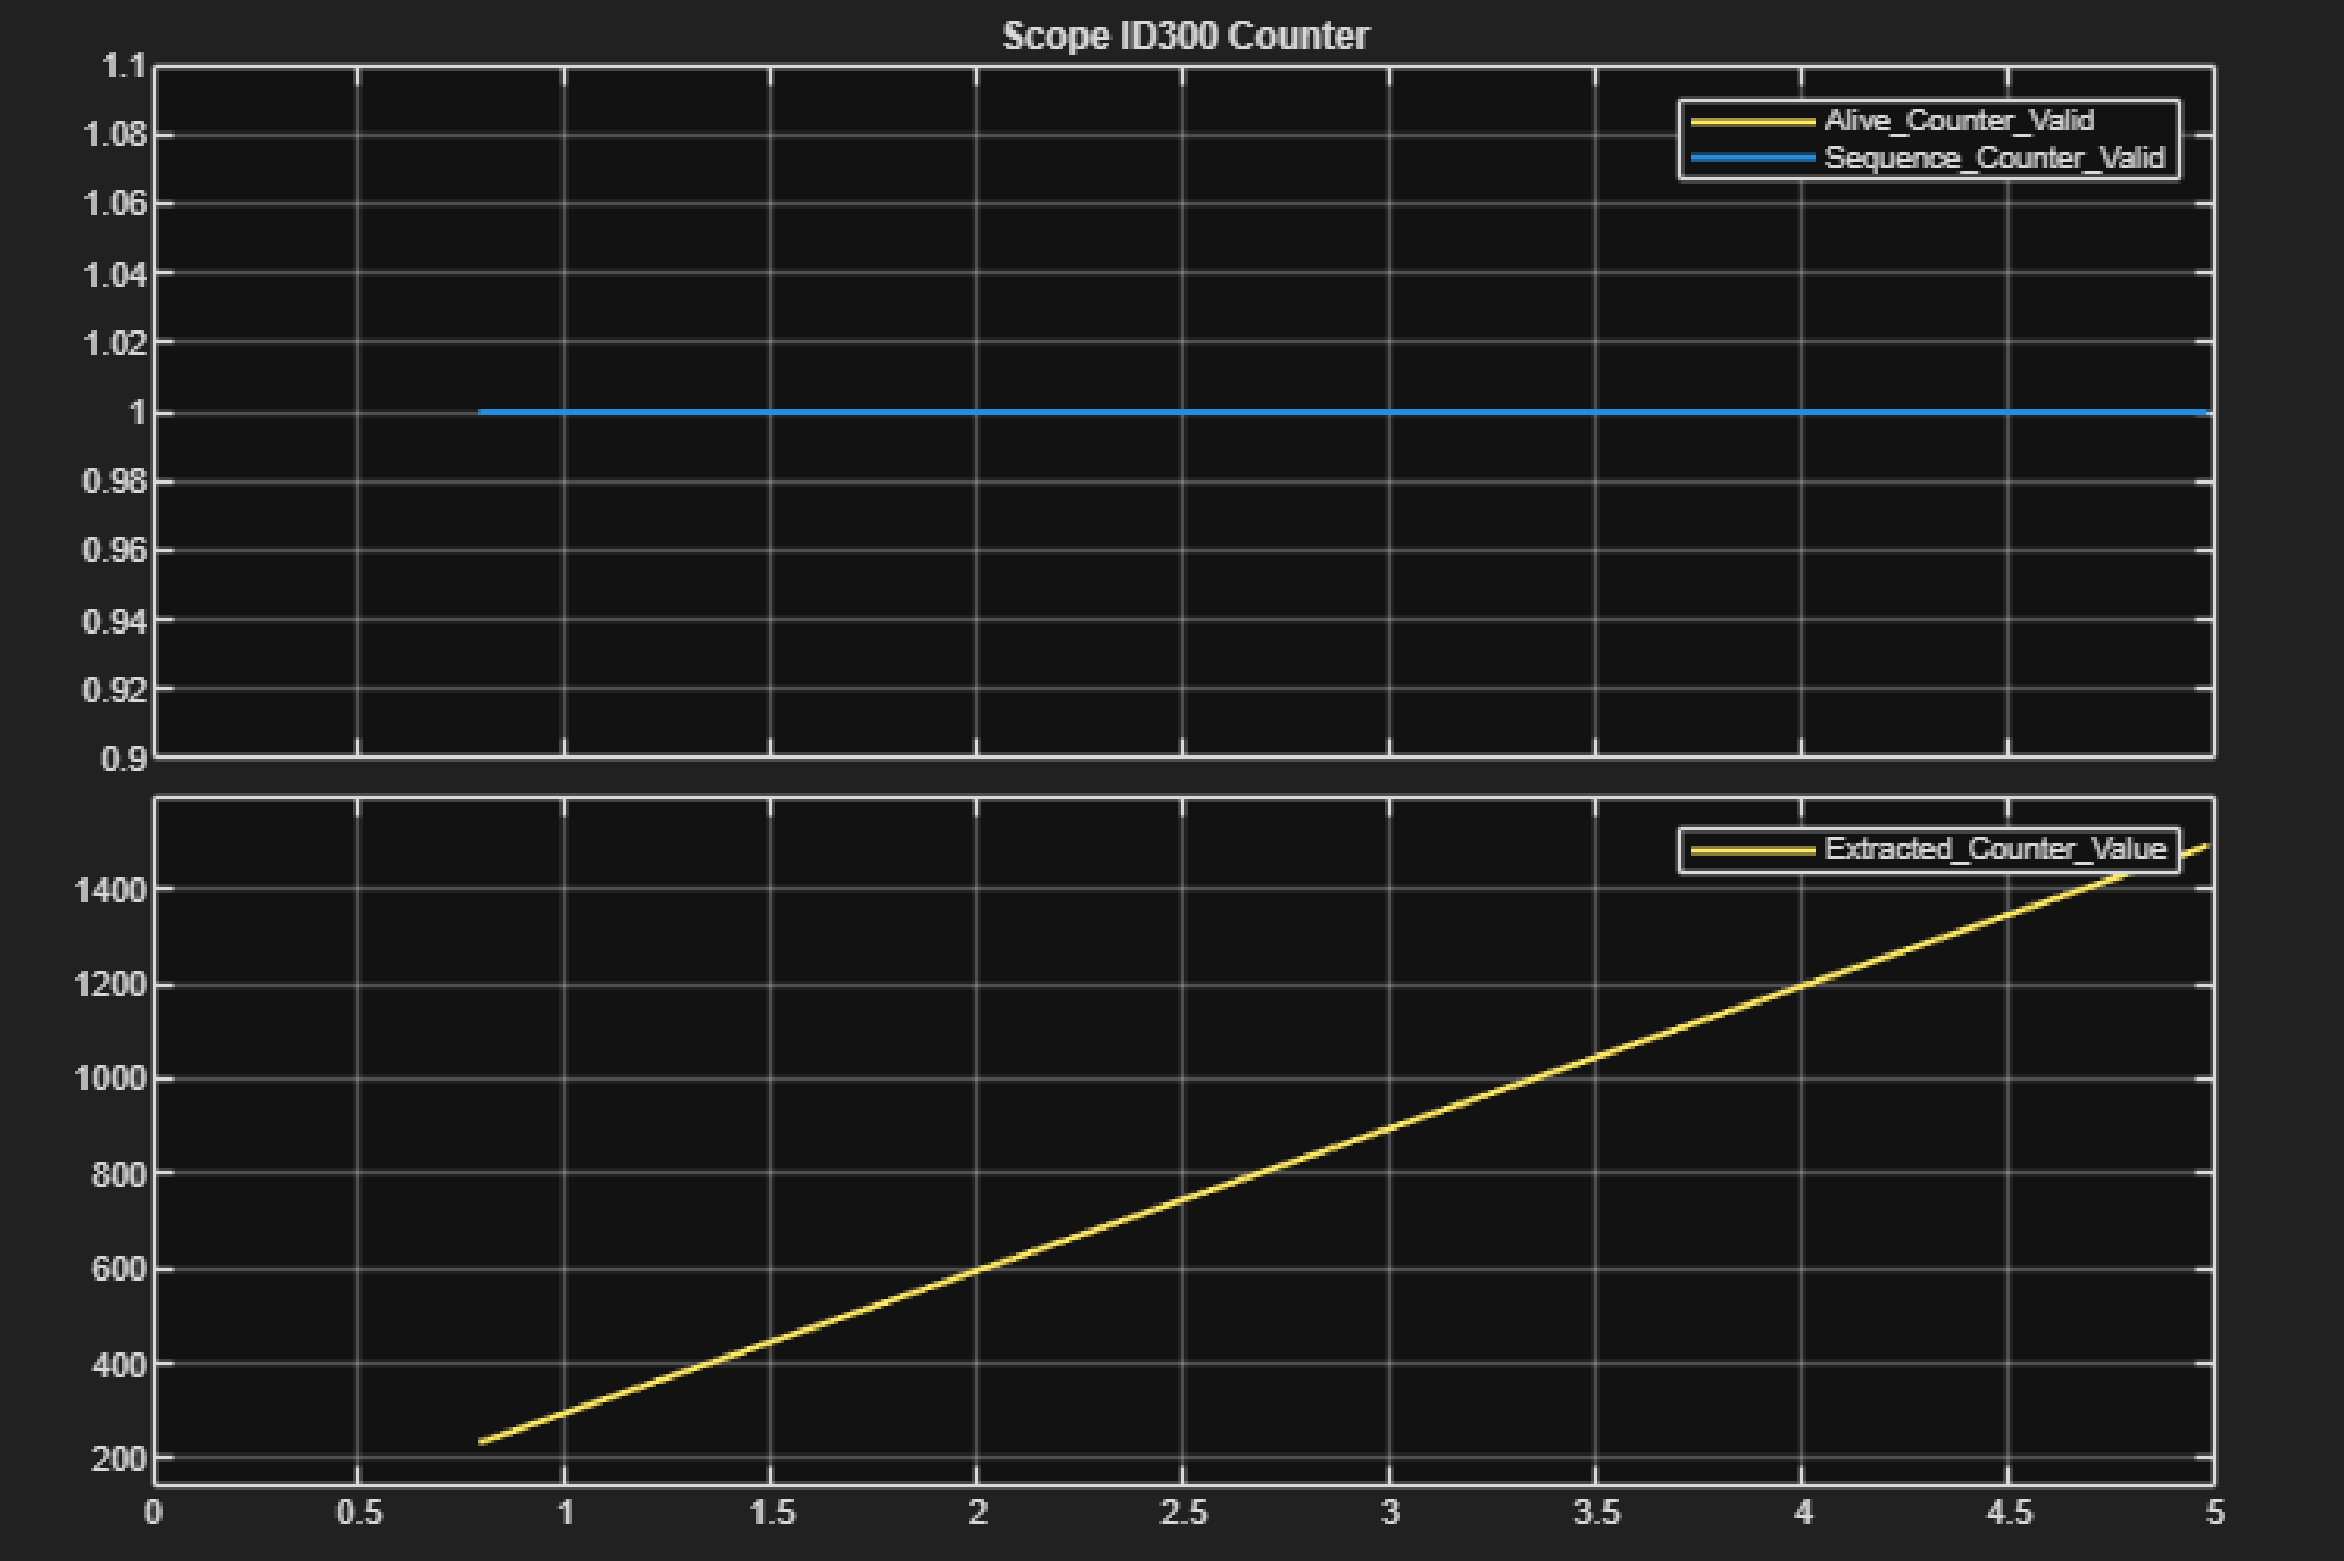

 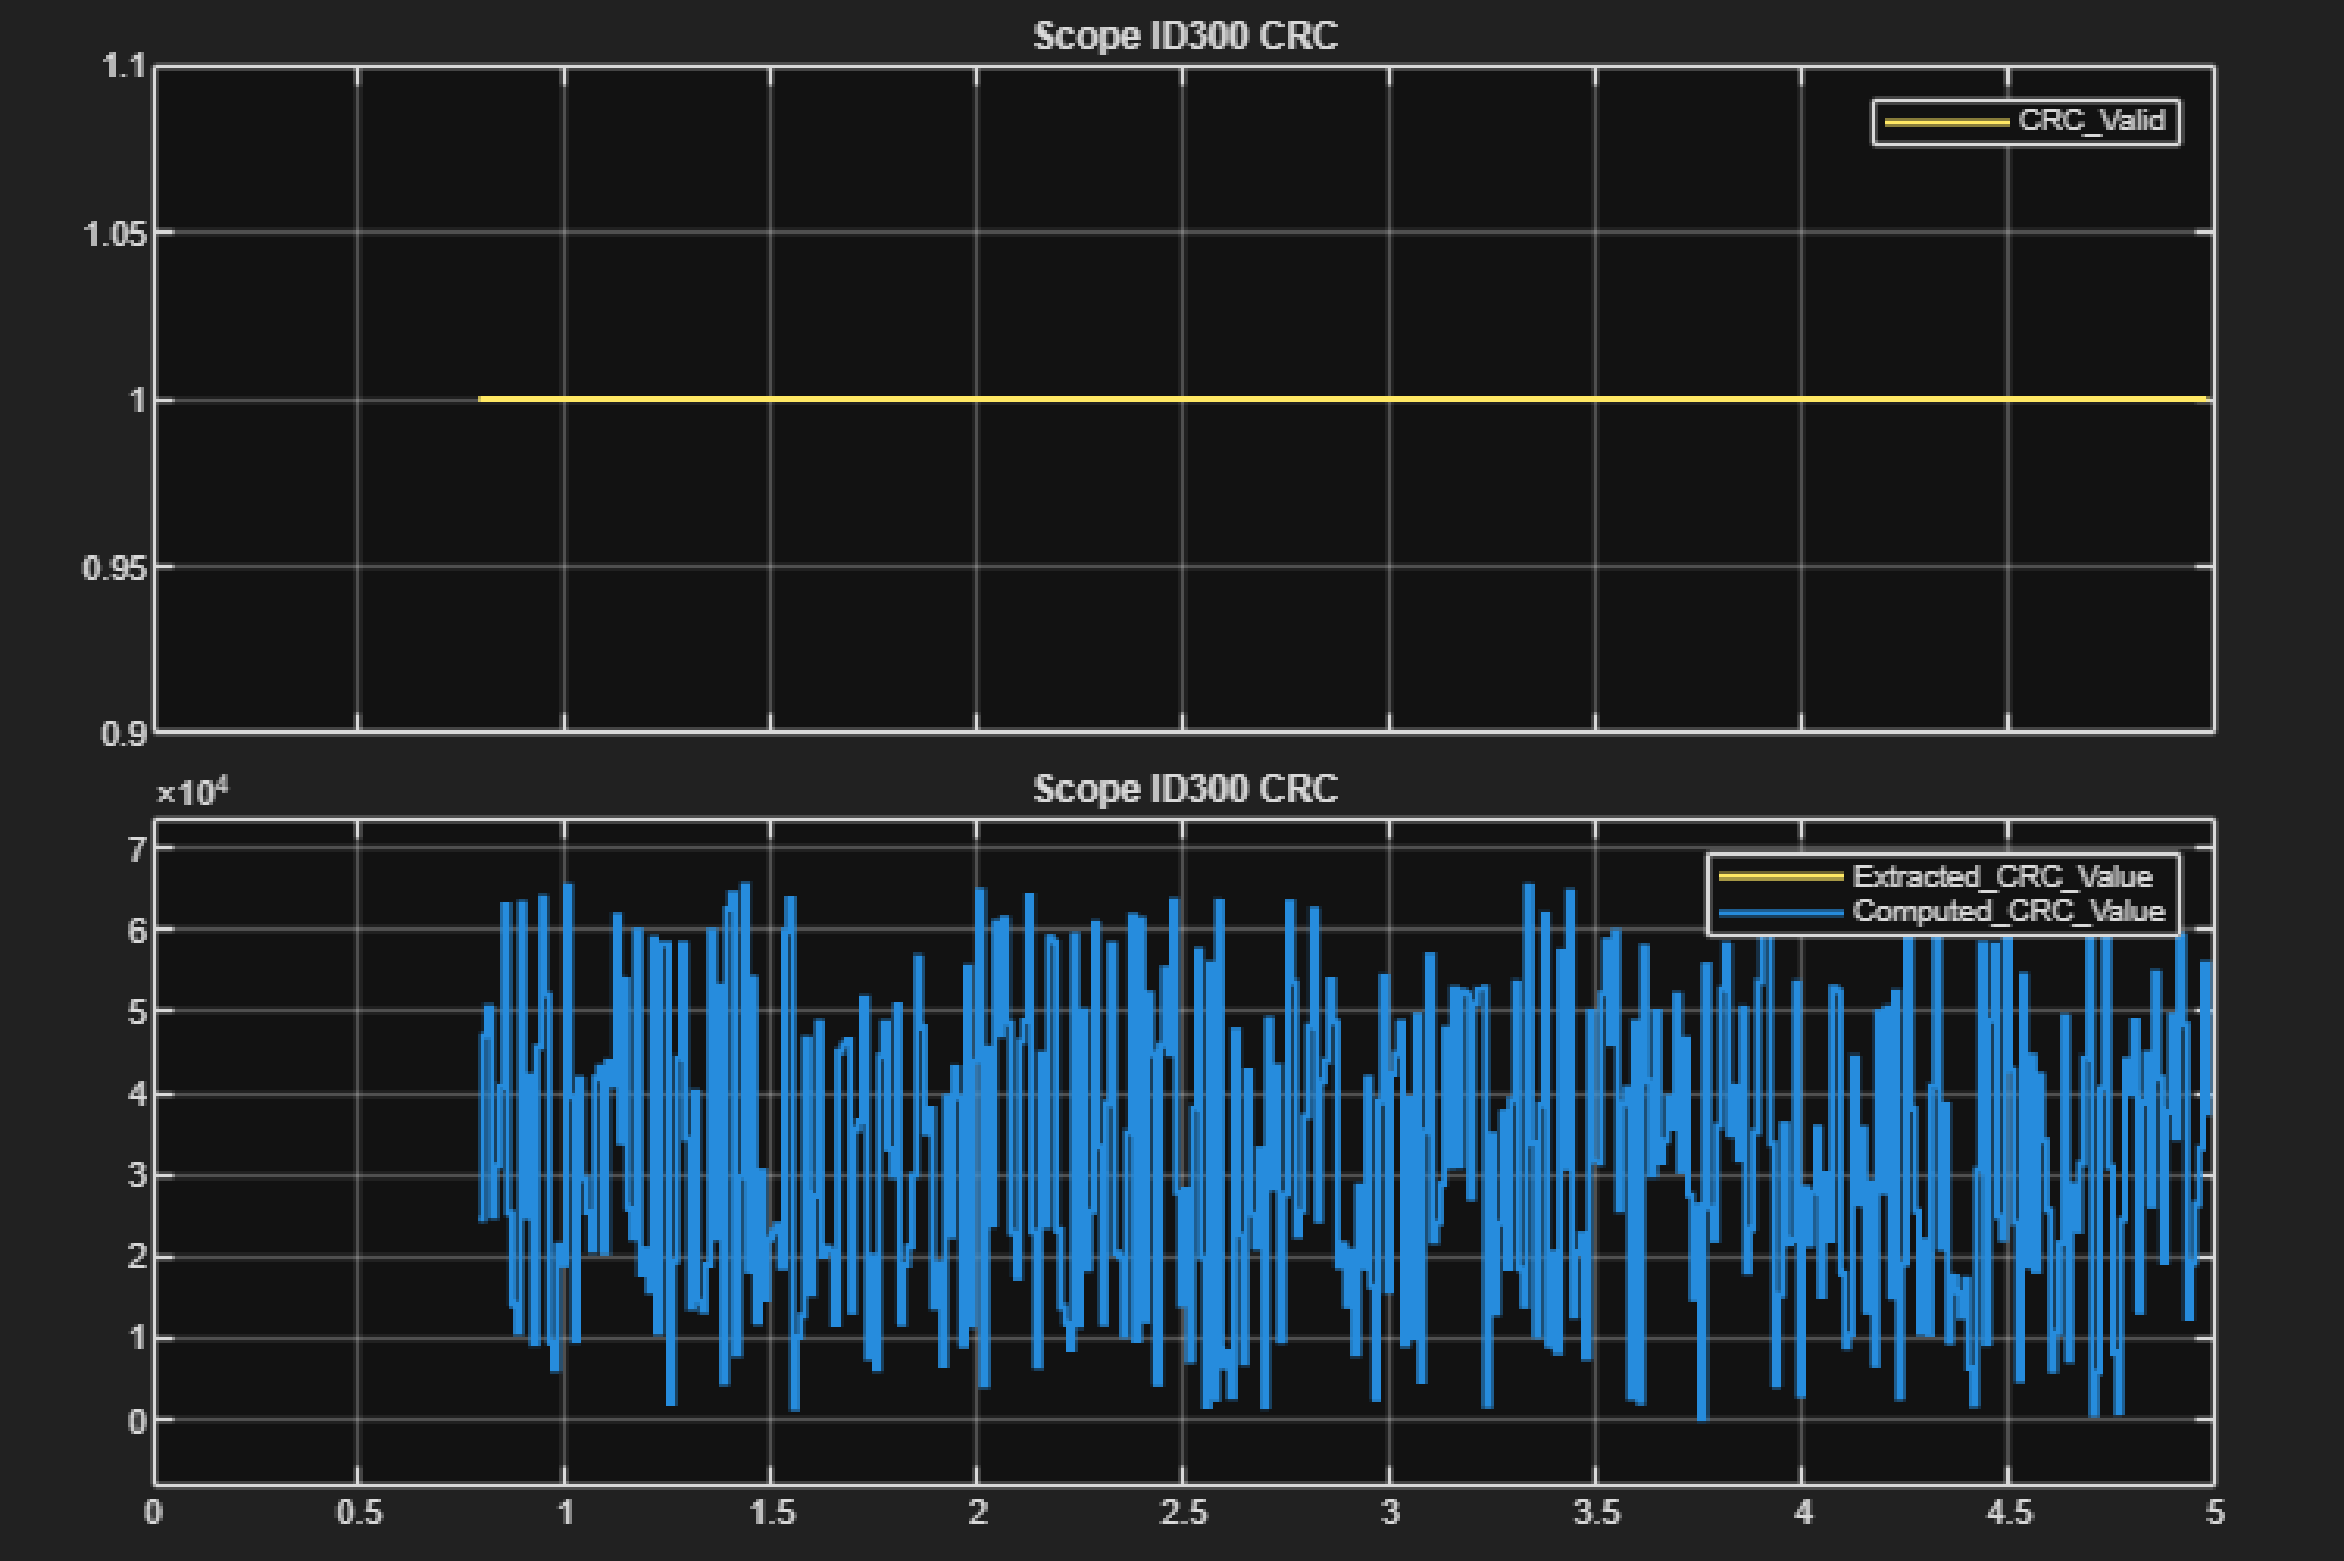

**CAN FD Read Ch2 - Message D ID400 - Counter 16-Bit and Custom CRC 12-bit**

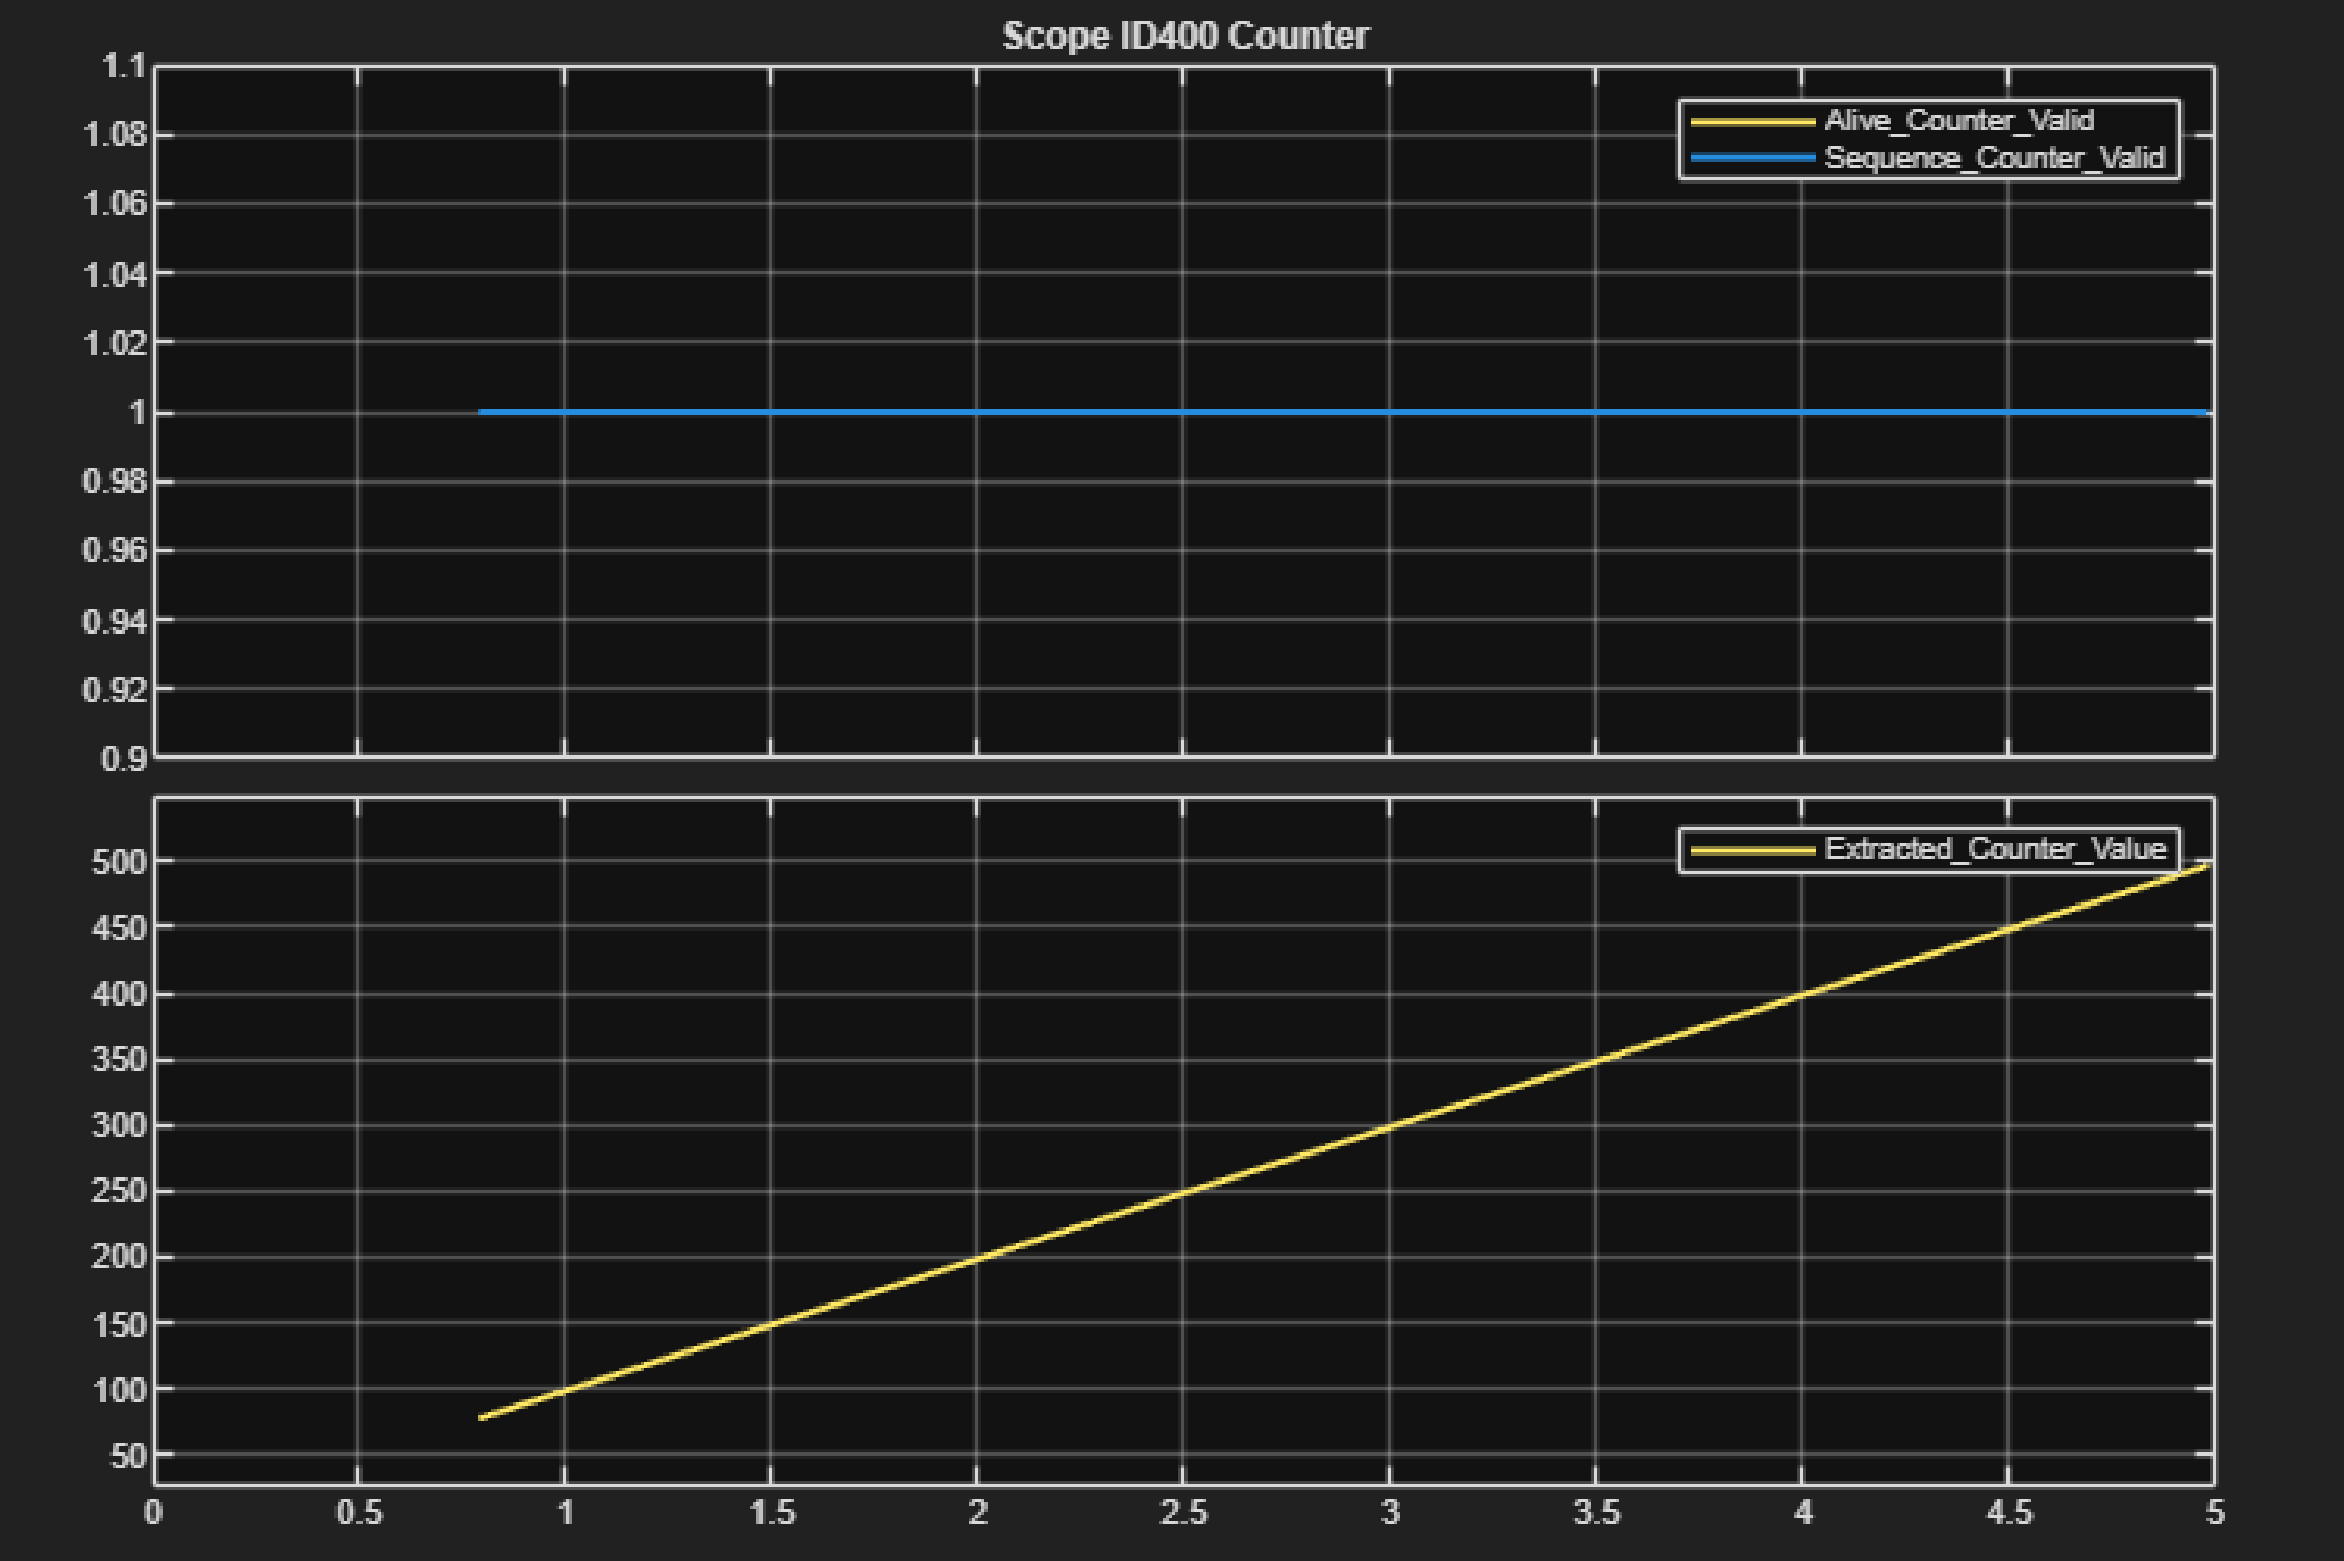

 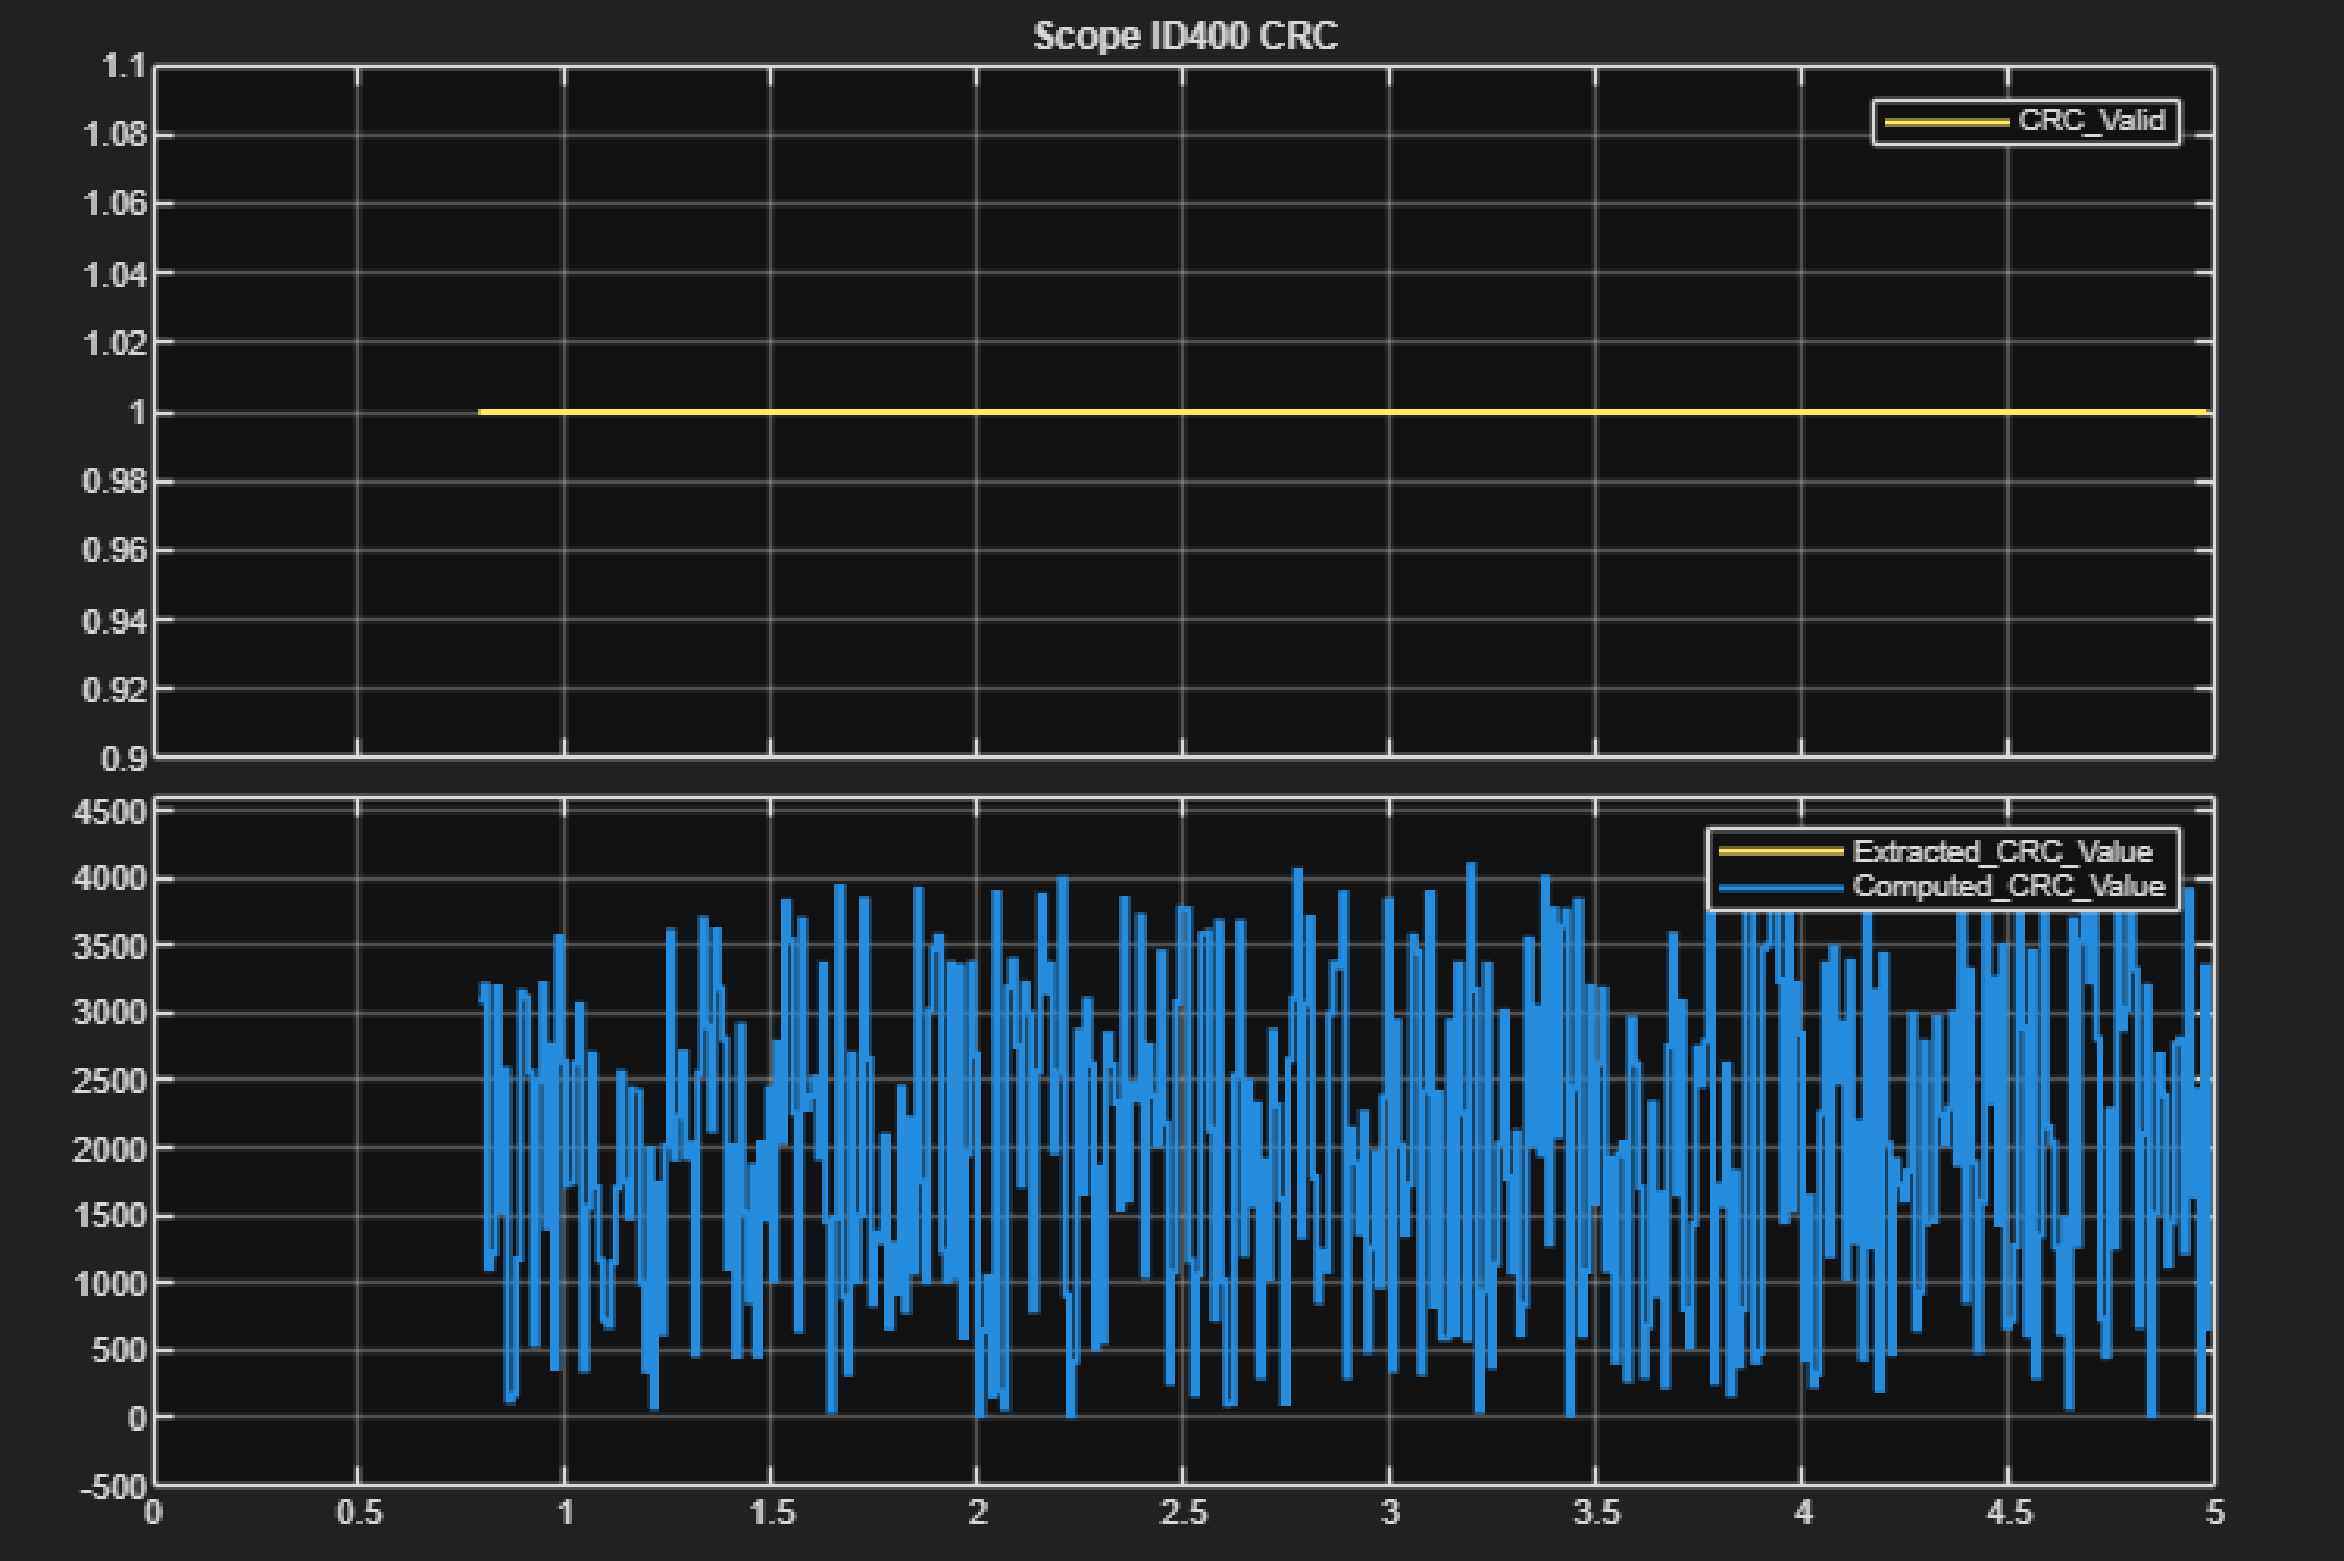

**CAN FD Read Ch2 - Message E ID500 - Counter 8-bit**

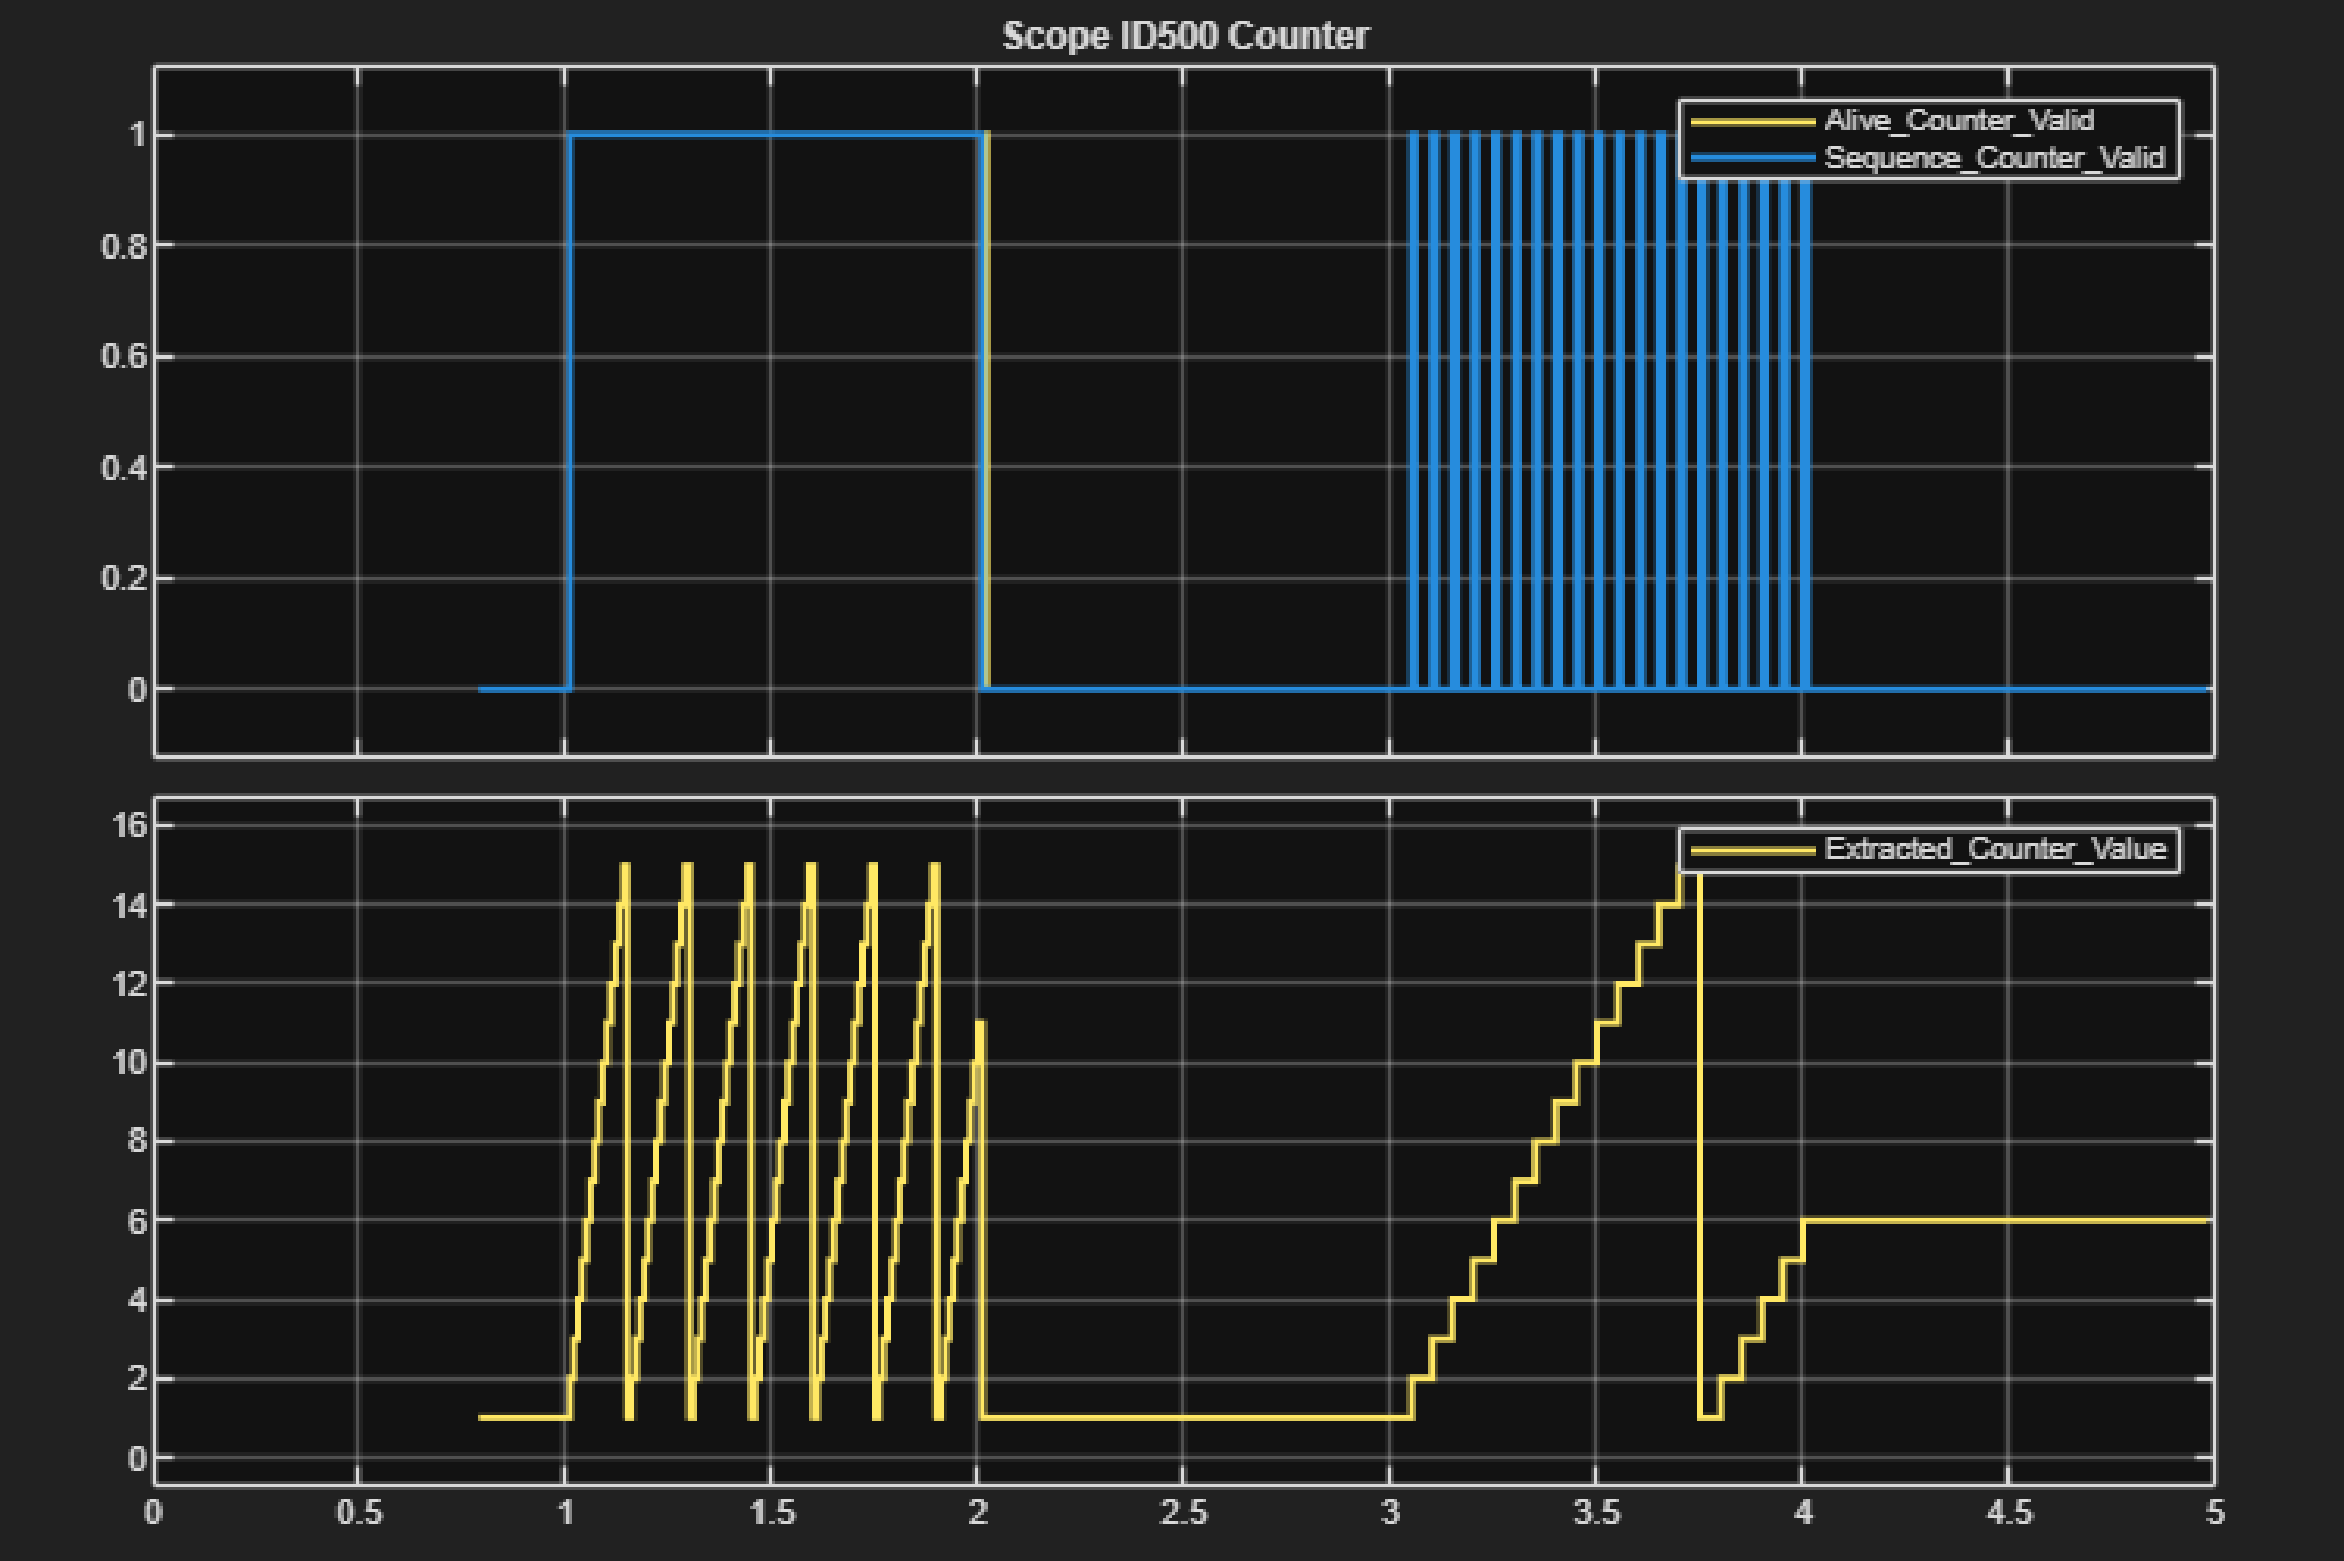 

## Additional References

- [IO602/IO603/IO691 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa)

- [Custom CRC Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_custom_crc_usage_notes)